# Make sensitivity Kernels

**Author**: Ivan Abakumov

**Publication date**: 27th August 2018

**E-mail**: abakumov_ivan@mail.ru

**Task**: make sensitivity kernels for two cases

- traveltime tomo

- FWI on diving waves

- FWI + reflection and diffractions

## Add MLIB

clear all; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
addmypath;

## Apply inversion settings

INV_settings;

s = 8;
acq.sx = acq.sx(s);
acq.sz = acq.sz(s)

acq = struct with fields:
    gsx: [151 159 167 175 183 191 199 207 215 223 231 239 247 255 263 271 279 287 295 303 311 319 327 335 343 351]
    gsz: [121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121 121]
    grx: [1×401 double]
    grz: [1×401 double]
     sx: 1950
     sz: 250
     rx: [1×401 double]
     rz: [1×401 double]


acq.gsx = acq.gsx(s);
acq.gsz = acq.gsz(s);

r = 250;
acq.rx = acq.rx(r);
acq.rz = acq.rz(r)

acq = struct with fields:
    gsx: 207
    gsz: 121
    grx: [1×401 double]
    grz: [1×401 double]
     sx: 1950
     sz: 250
     rx: 3.1125e+03
     rz: 0


acq.grx = acq.grx(r);
acq.grz = acq.grz(r);

## Calculate traveltimes of direct waves

tdir = zeros(length(acq.sx), length(acq.rx)); 

for s=1:length(acq.sx)
    S = [acq.sx(s), acq.sz(s)];
    tti = FSM2D(Gold,S,bvelmod);
    
    for r=1:length(acq.rx)
        tdir(s,r) = tti(acq.grx(r),acq.grz(r));
    end
end

tdir = round((tdir)/G.dt + 1); 

## Make sin filter

% 8 Hz
tfilter = ones(1,126);
tfilter(1:26) = sin(linspace(0, pi/2, 26)).^2;
tfilter(101:126) = sin(linspace(pi/2, 0, 26)).^2;
t = 0:G.dt:125*G.dt;
% 20 Hz


ti = 0:G.dt*fpeak/8:125*G.dt;
filter = interp1(t,tfilter,ti);

## FWI kernel (diving only)

%dV_fwi_dif = zeros(G.nx, G.nz); 
%dV_fwi_dif(target.xx,target.zz) = MLD('/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_ref_diff/FWI_First_dv_59.mat');
%velmod =  bvelmod + dV_fwi_dif; 
velmod = bvelmod; 
mvelmod = bvelmod; 

Grad = zeros(length(target.xx), length(target.zz)); 

for ishot=1:nthreads:length(acq.sx)

    shotnum = ishot:min(length(acq.sx), ishot+nthreads-1); 
 
    % baseline
    [f09,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod);
    s09 = zeros(length(acq.rx), G.nt, length(shotnum));
    for s=1:length(shotnum) 
        for i=1:length(acq.rx)
            minind = max(1,tdir(shotnum(s),i));
            maxind = min(G.nt, tdir(shotnum(s),i) + length(filter)-1);
            ind = minind:maxind;
            filt = zeros(G.nt,1);
            filt(ind) = filter(1:length(ind));
            s09(i, :, s) = squeeze(f09(acq.grx(i),acq.grz(i),:,s)); %.*filt;
        end
    end
    U = f09(target.xx,target.zz,:,:);  
    clear f09; 
 
    % monitor 
    [f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, mvelmod);
    s10 = zeros(length(acq.rx), G.nt,length(shotnum));
    for s=1:length(shotnum) 
        for i=1:length(acq.rx)
            minind = max(1,tdir(shotnum(s),i));
            maxind = min(G.nt, tdir(shotnum(s),i) + length(filter)-1);
            ind = minind:maxind;
            filt = zeros(G.nt,1);
            filt(ind) = filter(1:length(ind));
            s10(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s)); %.*filt;
        end
    end
    clear f10; 
         
    % residual seismograms        
    ds = s10-s09; 
    ds = ds(:, end:-1:1,:); 
          
    % adjoint state
    [q,~,~] = Get_FD_backward(G, acq, shotnum, fpeak, ds, velmod);
    Q = q(target.xx,target.zz,:,:);
    clear q
         
    % functional and gradient
    grad=make_grad_LS(G,U,Q);
    clear U Q

    Grad = Grad + grad;
end

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 1


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 1; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 55.050899 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 1


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 1; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 55.139166 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 1


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 1; nb = 1; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 1, stype = 0; wtype = 0; atype=1;
sxi[0] = 299; szi[0] = 100;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 100.067437 seconds.



Grad = Grad.*weight;
     
%% Calculate gradient and functional
% dJ/dm - is result of correlation
% now we multiply it by dm/dv   (m=1/v^2)
vel = bvelmod(target.xx, target.zz); 
Grad = -2*Grad./vel.^3; 
Const = (1e+18)/29;      
Grad = Const*Grad;
GradFWI_diving = Grad;

## FWI kernel (+reflected and diffracted)

%dV_fwi_dif = zeros(G.nx, G.nz); 
%dV_fwi_dif(target.xx,target.zz) = MLD('/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_ref_diff/FWI_First_dv_59.mat');
%velmod =  bvelmod + dV_fwi_dif; 
velmod = bvelmod; 
mvelmod = bvelmod;
mvelmod(141,291) = mvelmod(141,291) + 500;
mvelmod(141,251) = mvelmod(141,251) + 500;
mvelmod(161,251) = mvelmod(161,251) + 500;

Grad = zeros(length(target.xx), length(target.zz)); 

for ishot=1:nthreads:length(acq.sx)

    shotnum = ishot:min(length(acq.sx), ishot+nthreads-1); 
 
    % baseline
    [f09,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, velmod);
    s09 = zeros(length(acq.rx), G.nt, length(shotnum));
    for s=1:length(shotnum) 
        for i=1:length(acq.rx)
            minind = max(1,tdir(shotnum(s),i));
            maxind = min(G.nt, tdir(shotnum(s),i) + length(filter)-1);
            ind = minind:maxind;
            filt = zeros(G.nt,1);
            filt(ind) = filter(1:length(ind));
            s09(i, :, s) = squeeze(f09(acq.grx(i),acq.grz(i),:,s)); %.*filt;
        end
    end
    U = f09(target.xx,target.zz,:,:);  
    clear f09; 
 
    % monitor 
    [f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, mvelmod);
    s10 = zeros(length(acq.rx), G.nt,length(shotnum));
    for s=1:length(shotnum) 
        for i=1:length(acq.rx)
            minind = max(1,tdir(shotnum(s),i));
            maxind = min(G.nt, tdir(shotnum(s),i) + length(filter)-1);  %125
            ind = minind:maxind;
            filt = zeros(G.nt,1);
            filt(ind) = filter(1:length(ind));
            s10(i,:,s) = squeeze(f10(acq.grx(i),acq.grz(i),:,s)); %.*filt;
        end
    end
    clear f10; 
         
    % residual seismograms        
    ds = s10-s09; 
    ds = ds(:, end:-1:1,:); 
    
    % adjoint state
    [q,~,~] = Get_FD_backward(G, acq, shotnum, fpeak, ds, velmod);
    Q = q(target.xx,target.zz,:,:);
    clear q
         
    % functional and gradient
    grad=make_grad_LS(G,U,Q);
    clear U Q

    Grad = Grad + grad;
end

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 1


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 1; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 100.693953 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.09049 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 1


Stability parameter: 1.09048 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 1; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 56.325424 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 1


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 1; nb = 1; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 1, stype = 0; wtype = 0; atype=1;
sxi[0] = 299; szi[0] = 100;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 56.498242 seconds.



Grad = Grad.*weight;
     
%% Calculate gradient and functional
% dJ/dm - is result of correlation
% now we multiply it by dm/dv   (m=1/v^2)
vel = bvelmod(target.xx, target.zz); 
Grad = -2*Grad./vel.^3; 
Const = (1e+18)/29;      
Grad = Const*Grad;
   
GradFWI_diffracted = Grad;

## Plot results 


KERNEL = zeros(501,401,4);

%KERNEL(target.xx,target.zz,1) = GradTomo;
KERNEL(target.xx,target.zz,2) = GradFWI_diving;
KERNEL(target.xx,target.zz,3) = GradFWI_diffracted;
KERNEL(target.xx,target.zz,4) = GradFWI_diffracted-GradFWI_diving;

fig = figure('Position', [900 400 570 460])

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 570 460]
       Units: 'pixels'

  Show all properties


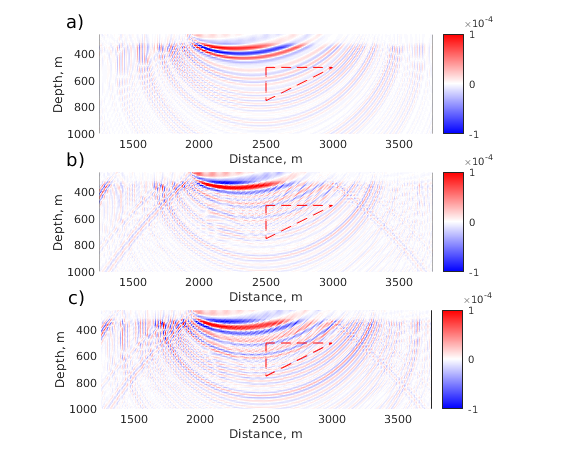


subplot(3,1,1)
pcolor(G.xx, G.zz, KERNEL(:,:,2)');
shading interp
caxis([-0.0001 0.0001])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(1000,150,'a)','FontSize',14)

subplot(3,1,2)
pcolor(G.xx, G.zz, KERNEL(:,:,3)');
shading interp
caxis([-0.0001 0.0001])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(1000,150,'b)','FontSize',14)

subplot(3,1,3)
pcolor(G.xx, G.zz, KERNEL(:,:,4)');
shading interp
caxis([-0.0001 0.0001])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(1000,150,'c)','FontSize',14)


colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%colormap('gray')